# IIR elliptic BPF model

## Configure input parameters:

Sampling frequency [Hz] 

Fo =8096

Fo = 8096

T = 1/Fo;

Bits per sample

NumOfBits = 16

NumOfBits = 16

Filter passband

fp = [1500 2800];
Wp=fp/(Fo/2); % normalized passband

Filter stopband

fs = [1000 3000];
Ws=fs/(Fo/2); % normalized stopband

Filter ripples

max ripple in passband [dB]

Rp = 1

Rp = 1

min ripple in stopband [dB]

Rs =30

Rs = 30

Input test signal 

t = 0:T:1; % time scale [s]
x_in = zeros(size(t)); 
x_in(1) = 2^(NumOfBits-1);

% scale the input signal to base 2
scal_coef = max(abs(x_in));
scal_2 = ceil(log2(scal_coef));
x_scaled = x_in/(2^scal_2);
% save in memory (quantized)
x = quantization(x_scaled, NumOfBits, 1);

**Direct realization - MATLAB reference**

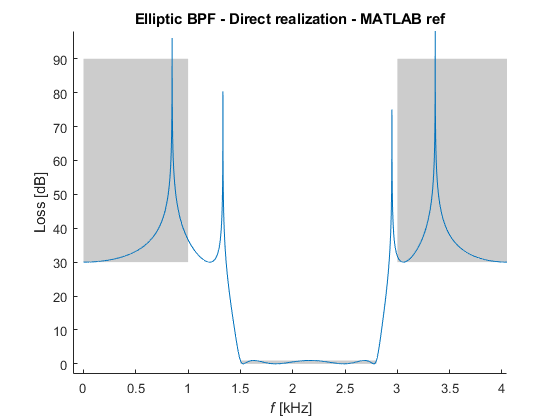

[N,Wn] = ellipord(Wp,Ws,Rp,Rs);
[b,a] = ellip(N,Rp,Rs,Wn);
order = 2*N; % for BPF
[H,w] = freqz(b,a,Fo);
figure
hold on
f = (w/pi)*Fo/2;
Loss = -20*log10(abs(H));
rectangle('Position',[0, (Rs), fs(1)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(f/1000, Loss)
title('Elliptic BPF - Direct realization - MATLAB ref')
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])

**Direct realization - DSP Simulation**

*s* – scaling coefficient

% scale the filter coeffs to base 2
scal_coef = max(abs([b a]));
scal_coef = ceil(log2(scal_coef));
b_scal = b/(2^scal_coef);
a_scal = a/(2^scal_coef);
% save in memory (quantized)
b_q = quantization(b_scal,NumOfBits,1);
a_q = quantization(a_scal,NumOfBits,1);


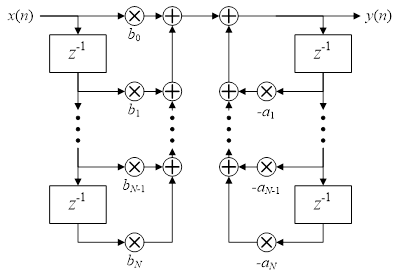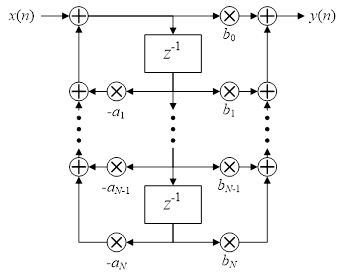

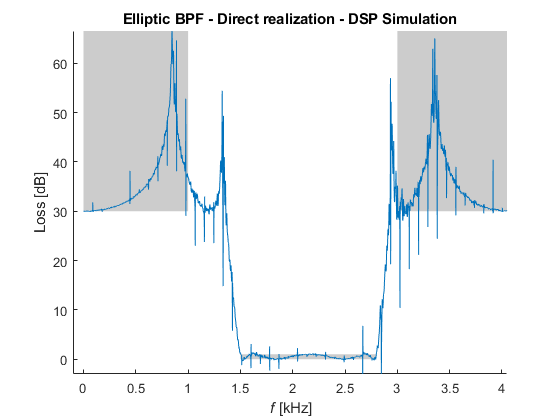

% filtering and save in memory (quantized)
z = zeros(1,order);
xzak = zeros(1,order);

for n=1:length(x)
    z(order)=quantization(b_q(order+1)*xzak(order),NumOfBits,1);
    for ind=order:-1:2
    z(ind-1)=quantization(z(ind)+b_q(ind)*xzak(ind-1),NumOfBits,1);
    end
    w(n)=quantization(z(1)+b_q(1)*x(n),NumOfBits,1);
    for zak=order:-1:2
        xzak(zak)=xzak(zak-1);
    end
    xzak(1)=x(n);
end
yzak = zeros(1,order);
s = zeros(1,order);
y = zeros(1,order);
for n=1:length(x)
    s(order)=quantization(-a_q(order+1)*yzak(order),NumOfBits,1);
    for ind=order:-1:2
    s(ind-1)=quantization(s(ind)-a_q(ind)*yzak(ind-1),NumOfBits,1);
    end
    y(n) = quantization((w(n)+s(1)),NumOfBits,1)*2^scal_coef;
    for zak=order:-1:2
        yzak(zak)=yzak(zak-1);
    end
    yzak(1)=y(n);
end

figure
hold on
Y = fft(y);
M = abs(Y);
Loss = -20*log10(M);
Faxis=0:Fo;
rectangle('Position',[0, (Rs), fs(1)/1000-0, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(Faxis(1:Fo/2)/1000, Loss(1:Fo/2))
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])
title('Elliptic BPF - Direct realization - DSP Simulation')

**Cascade realisation - MATLAB reference**

[sos,G] = tf2sos(b,a);
%Transfer Function to Second Order Section conversion
%SOS is an L by 6 matrix with the following structure:
% SOS = [ b01 b11 b21  1 a11 a21 
%         ...
%         b0L b1L b2L  1 a1L a2L ]
 
%Each row of the SOS matrix describes a 2nd order transfer function:
%                 b0k +  b1k z^-1 +  b2k  z^-2
%      Hk(z) =  -------------------------------
%                 1 +  a1k z^-1 +  a2k  z^-2 
%where k is the row index.
 
%G is a scalar which accounts for the overall gain of the system. If
%G is not specified, the gain is embedded in the first section. 
% The second order structure thus describes the system H(z) as:
%        H(z) = G*H1(z)*H2(z)*...*HL(z)

v = size(sos); NumOfSections = v(1);

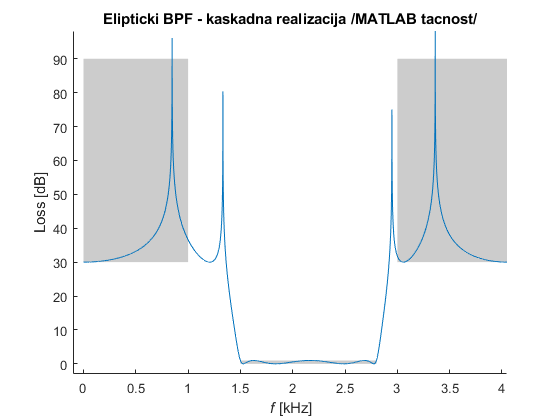

Hcas = G;
for i=1:NumOfSections
      bi=sos(i, 1:3);
      ai=sos(i, 4:6);  
      [Hi,w]=freqz(bi,ai,Fo);
      Hcas=Hcas.*Hi;
end

figure
f = (w/pi)*Fo/2;
Loss = -20*log10(abs(Hcas));
hold on
rectangle('Position',[0, (Rs), fs(1)/1000-0, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(f/1000, Loss)
title('Elliptic BPF - Cascade realization - MATLAB ref')
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])

**Cascade realization - DSP Simulation**

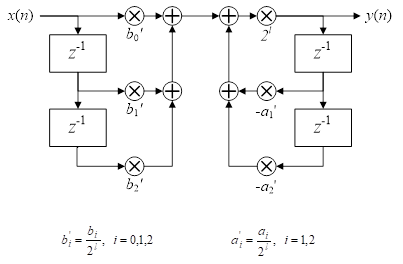

    

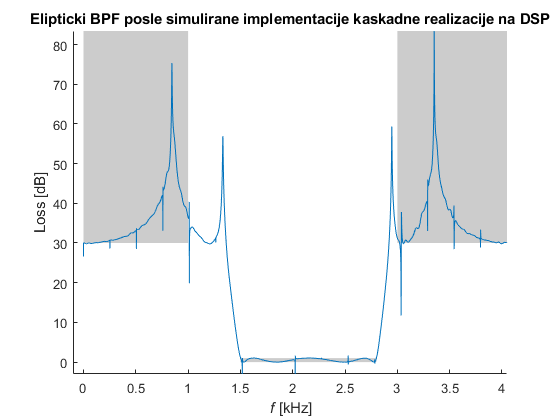

% scale the filter coeffs to base 2, for each section
skal_k_sek = zeros(1,3);
skal_k2_sek = zeros(1,3);
for i=1:NumOfSections
      b_sek=sos(i, 1:3);
      a_sek=sos(i, 4:6); 
      skal_k_sek(i)=max(abs([b_sek a_sek])); 
      skal_k2_sek(i)=ceil(log2(skal_k_sek(i)));
end
  
% filtering and save in memory (quantized)
Gk = quantization(G,NumOfBits,1);
ws=zeros(size(x)); ys=zeros(size(x)); xs=Gk*x;
for i=1:NumOfSections
    b_p0=sos(i, 1)/(2^skal_k2_sek(i));
    b_p0k=quantization(b_p0,NumOfBits,1);
    
    b_p1=sos(i, 2)/(2^skal_k2_sek(i));
    b_p1k=quantization(b_p1,NumOfBits,1);
    
    b_p2=sos(i, 3)/(2^skal_k2_sek(i));
    b_p2k=quantization(b_p2,NumOfBits,1);

    a_p1=sos(i, 5)/(2^skal_k2_sek(i));
    a_p1k=quantization(a_p1,NumOfBits,1);
    
    a_p2=sos(i, 6)/(2^skal_k2_sek(i));
    a_p2k=quantization(a_p2,NumOfBits,1);
    
    x2=0;x1=0;    
    for n=1:length(xs)
        z2=quantization(b_p2k*x2,NumOfBits,1);
        z1=quantization(z2+b_p1k*x1,NumOfBits,1);
        ws(n)=quantization(z1+b_p0k*xs(n),NumOfBits,1);
        x2=x1;
        x1=xs(n);
    end
    y2=0;y1=0;
    for n=1:length(xs)
        v2=quantization(-a_p2k*y2,NumOfBits,1);
        v1=quantization(v2-a_p1k*y1,NumOfBits,1);
        ys(n)=quantization(ws(n)+v1,NumOfBits,1)*2^skal_k2_sek(i);
        y2=y1;
        y1=ys(n);
    end
    xs=ys;
end
y_kas=xs;

figure
hold on
Ykas=fft(y_kas);
Mkas=abs(Ykas);
Loss = -20*log10(Mkas);
Faxis = 0:Fo;
rectangle('Position',[0, (Rs), fs(1)/1000-0, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fs(2)/1000, (Rs), (Fo/2)/1000-fs(2)/1000, 2*Rs],'FaceColor',[.8 .8 .8],'Linestyle','none')
rectangle('Position',[fp(1)/1000, 0, fp(2)/1000-fp(1)/1000, Rp],'FaceColor',[.8 .8 .8],'Linestyle','none')
plot(Faxis(1:Fo/2)/1000, Loss(1:Fo/2))
xlabel('{\it f} [kHz]'), ylabel('Loss [dB]')
axis([-0.1,(Fo/2)/1000, -3,max(Loss)])
title('Elliptic BPF - Direct realization - DSP Simulation')